clear all;
FilePath = "C:\Users\adity\Desktop\hack-nc-25";
NCDF_X = ncread(FilePath+"\data_set.nc",'x');
NCDF_Y = ncread(FilePath+"\data_set.nc",'y');
NCDF_T =  ncread(FilePath+"\data_set.nc",'time');
NCDF_AT_ED = zeros(size(NCDF_X,1),size(NCDF_Y,1));

v = VideoWriter(FilePath+"\out.avi",'Uncompressed AVI'); 
open(v);
outtxtfile = fopen(FilePath+"\outtxt1.txt","w");

slice = 20;

for t=1:(80/slice)

NCDF_RH = ncread(FilePath+"\data_set.nc",'relative_humidity',[1 1 t*slice],[2530 2706 1]);
NCDF_AT = ncread(FilePath+"\data_set.nc",'air_temperature',[1 1 t*slice],[2530 2706 1]);

NCDF_AT_mean = sum(NCDF_AT(~isnan(NCDF_AT)))/numel((NCDF_AT(~isnan(NCDF_AT))));
NCDF_AT(~isnan(NCDF_AT)) = (NCDF_AT(~isnan(NCDF_AT))-NCDF_AT_mean);
NCDF_AT(isnan(NCDF_AT)) = 0;
NCDF_AT_ED = (mat2gray(imerode(imfilter(NCDF_AT+imfilter(NCDF_AT,fspecial("laplacian")),fspecial("gaussian",3,1)),strel('disk',3)))>.5);

NCDF_RH_mean = sum(NCDF_RH(~isnan(NCDF_RH)))/numel((NCDF_RH(~isnan(NCDF_RH))));
NCDF_RH(~isnan(NCDF_RH)) = (NCDF_RH(~isnan(NCDF_RH))-NCDF_AT_mean);
NCDF_RH(isnan(NCDF_RH)) = 0;

frame = cat(3,permute(mat2gray(clip(NCDF_AT,0,100)),[2 1]),permute(mat2gray(clip(-NCDF_AT,0,100)),[2 1]),permute(mat2gray(clip(NCDF_RH,0,100)),[2 1]));
writeVideo(v, frame);

end

close(v);

fprintf("render done");

render done

imageViewer(mat2gray(NCDF_AT_ED));

numplotel = 20;
NCDF_AT_ED_P = regionprops(NCDF_AT_ED,'centroid','Area');
CTOID = reshape([NCDF_AT_ED_P(:).Centroid],2,[] )';
AREAS = reshape([NCDF_AT_ED_P(:).Area],1,[] )';

% Sort the first list and get the sorting indices
[AREAS, sort_indices] = sort(AREAS,'descend');

% Use the sorting indices to reorder the second list
CTOID = CTOID(sort_indices,:);

CTOID = CTOID(1:numplotel,:);
AREAS = AREAS(1:numplotel,:);
C1 = [36.137 -79.0075];
C2 = [36.137 -78.7540];
C3 = [0 1];
x_stride = C1(1)-C2(1)

x_stride = 0

y_stride = C1(2)-C3(2)

y_stride = -80.0075

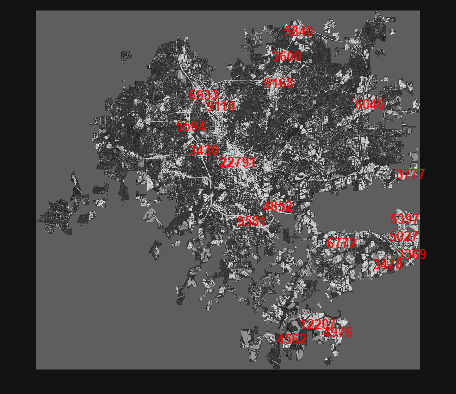

for i=1:numel(CTOID(:,1))
fprintf(outtxtfile,"%f %f\n",36.137016564593324-0.0001000227604283435*CTOID(i,1),-79.00752291761101+0.0001000100678631108*CTOID(i,2));
end

fclose(outtxtfile);
imshow(mat2gray(NCDF_AT));
hold on;
Hpl = text(CTOID(:,1),CTOID(:,2),num2str(AREAS(:)),'FontWeight','bold','HorizontalAlignment','center','backgroundColor','none','Color','r');

drawnow;


